# **Communication Systems**

#### Dr Mohammad Hadi

Seyyed Amirmahdi Sadrzadeh | 401102015

Anita Gholizadeh | 401102326

Seyyed Ali Nouri | 401102734

## a. Preparing the communication system

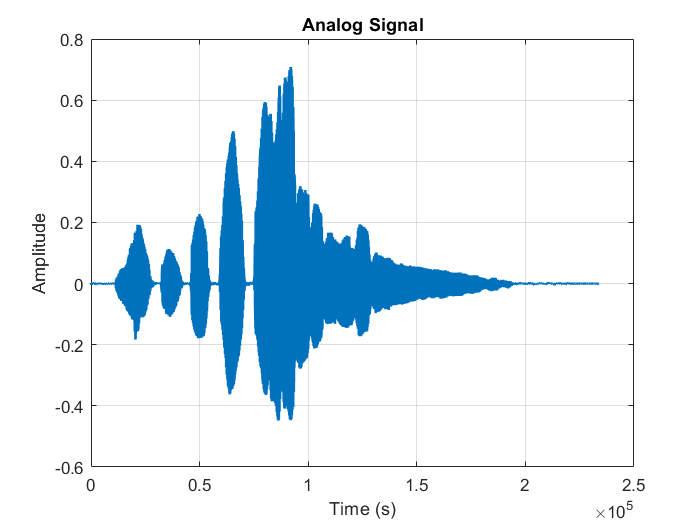

clear; close all; clc;

filePath  = 'audio.wav';
[myVoice, Fs_main] = audioread(filePath);
sound(myVoice, Fs_main);
figure;
plot(myVoice, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Analog Signal');
grid on;

### Defining Parameters

Delta_ADC = 0.01;
fs = 4000;
r_LC = 500;
A_vals = [0.1, 0.5, 2, 5, 10];
fc_ASK = 20000;
BW_CH = 1000;
N0_vals = [1e-6, 1e-4, 5e-4, 1e-2, 1e-1, 1];

### 1) ADC

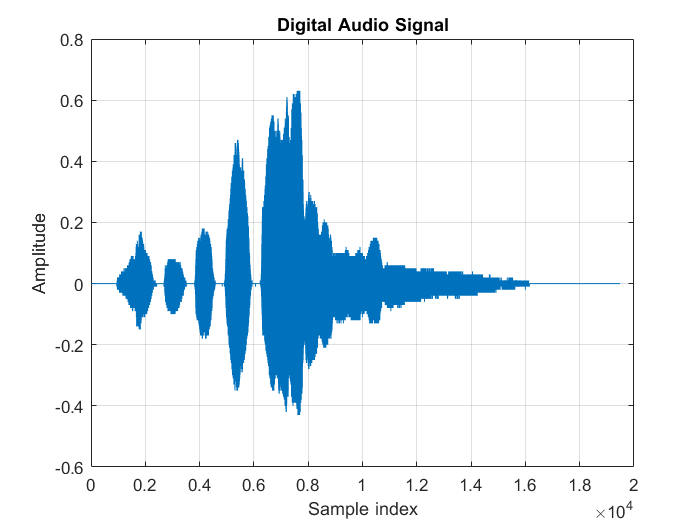

[Quantized_Signal, fsUsed, M] = ADC(filePath, fs, Delta_ADC);
figure;
plot(Quantized_Signal);
title('Digital Audio Signal');
xlabel('Sample index');
ylabel('Amplitude');
grid on;

#### Starting the loop

BER_mat = zeros(length(A_vals), length(N0_vals));
for aIdx = 1:length(A_vals)
    current_A = A_vals(aIdx);
    for nIdx = 1:length(N0_vals)

### 2) Line coder

        [~, Line_Coded_Signal] = linecoder(Quantized_Signal, r_LC, A_vals(aIdx), M);

### 3) ASK modulator

        [ASK_Signal, ~] = ASKModulator(Line_Coded_Signal, M, fc_ASK, fs, r_LC, A_vals(aIdx));

## b. Passing the voice for different N0

        current_N0 = N0_vals(nIdx);

### 4) Channel: Pass current noise level

        [rxSignal, ~] = channelAWGN(ASK_Signal, BW_CH, current_N0);

### 5) ASK demodulator

        Demodulated_Signal = ASKDemodulator(rxSignal, fc_ASK, fs, r_LC, A_vals(aIdx));

### 6) Line decoder

        bitsRx = lineDecoder(Demodulated_Signal, fs, r_LC, M);

### 7) DAC

        analogSig = DAC(bitsRx, fs, fsUsed);

### Play the received audio

%         sound(analogSig, fsUsed);
%         fprintf('Playing received audio for N0 = %e\n', current_N0);
%         pause(5);

## c. Calculating BER

        bit_errors = sum(Line_Coded_Signal(:) ~= Demodulated_Signal(:));
        BER_mat(aIdx, nIdx) = bit_errors / numel(Line_Coded_Signal);
    end
end

### Plotting

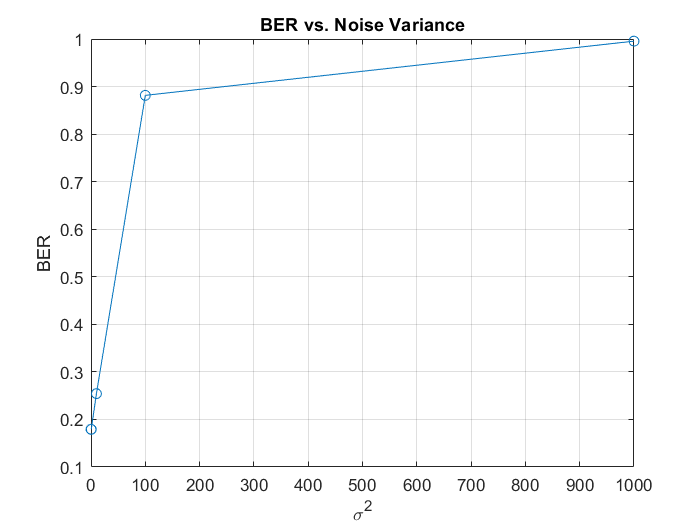

% BER vs. Noise Variance (for a fixed amplitude)
figure;
plot(N0_vals .* BW_CH, BER_mat(5, :), '-o');  % using the second amplitude value as an example
xlabel('\sigma^2');
ylabel('BER');
title('BER vs. Noise Variance');
grid on;

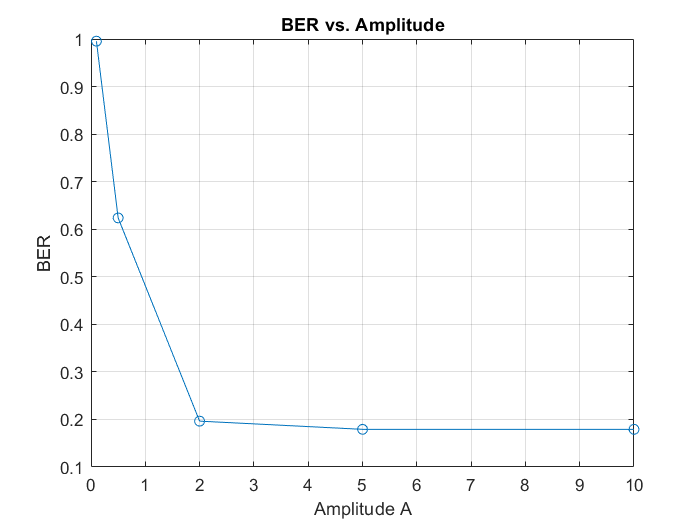


% BER vs. Amplitude (for a fixed noise level)
fixedN0_index = 2;  % choose one of the N0 values
figure;
plot(A_vals, BER_mat(:, fixedN0_index), '-o');
xlabel('Amplitude A');
ylabel('BER');
title('BER vs. Amplitude');
grid on;

## d. Non-Ideal channel with ISI

passing the signal for $N_0 =1\times {10}^{-6}$ and $A=15$.

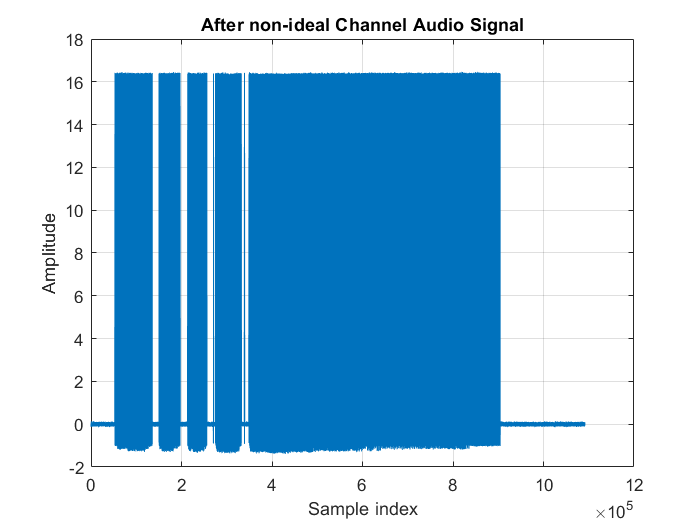

a = 15;
N0 = 1e-6;

[~, LCS] = linecoder(Quantized_Signal, r_LC, a, M);
[ASK_S, t] = ASKModulator(LCS, M, fc_ASK, fs, r_LC, a);

[rx, noiseVec] = NonIdealChannel(ASK_S, fs, BW_CH, N0);
figure;
plot(rx);
title('After non-ideal Channel Audio Signal');
xlabel('Sample index');
ylabel('Amplitude');
grid on;


Demodulated = ASKDemodulator(rx, fc_ASK, fs, r_LC, a);
bits = lineDecoder(Demodulated, fs, r_LC, M);
received = DAC(bits, fs, fsUsed);

#### Plotting the final signal

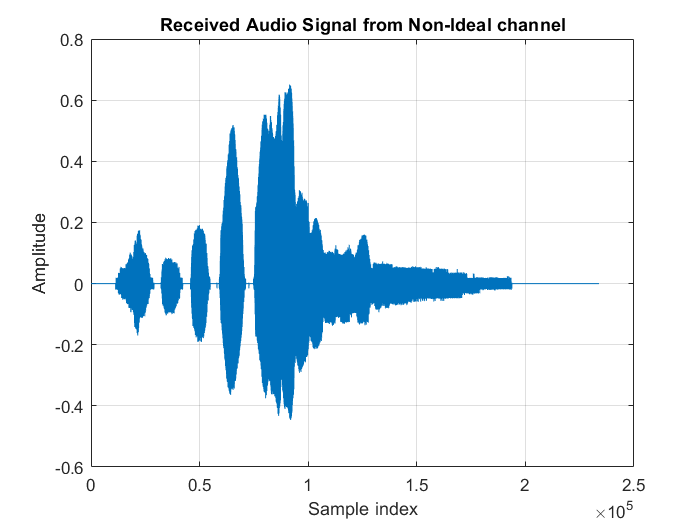

figure;
plot(received);
title('Received Audio Signal from Non-Ideal channel');
xlabel('Sample index');
ylabel('Amplitude');
grid on;

#### Playing the received audio

sound(analogSig, fsUsed);
fprintf('Playing received audio for N0 = %e\n', N0);

Playing received audio for N0 = 1.000000e-06


#### BER

bit_error = sum(LCS(:) ~= Demodulated(:));
BER = bit_error / numel(LCS);
fprintf('BER = %e\n', BER);

BER = 1.792055e-01


INCOMPLETE (For different A and N0)

## e. Impact of $f_s$ and $\Delta \;$

#### Impact of $\Delta$

clear;
clc;

filePath  = 'audio.wav';

delta_vals = [0.005, 0.01, 0.05, 0.1, 0.2];
a = 10;
N0 = 1e-5;
fs = 4000;
r_LC = 500;
fc_ASK = 20000;
BW_CH = 1000;

Org_Signals = [];
Final_Signals = [];
for d = delta_vals
    [Quantized_Signal, fsUsed, M] = ADC(filePath, fs, d);
    Org_Signals = [Org_Signals; Quantized_Signal];
    
    [~, Line_Coded] = linecoder(Quantized_Signal, r_LC, a, M);
    [ASK, ~] = ASKModulator(Line_Coded, M, fc_ASK, fs, r_LC, a);
    [rx, ~] = channelAWGN(ASK, BW_CH, N0);
    Demodulated = ASKDemodulator(rx, fc_ASK, fs, r_LC, a);
    bitsR = lineDecoder(Demodulated, fs, r_LC, M);
    final = DAC(bitsR, fs, fsUsed);
    
    sound(final, fsUsed);
    fprintf('Playing received audio for delta = %e\n', d);
    pause(5);
    
    Final_Signals = [Final_Signals; final];
end

Playing received audio for delta = 5.000000e-03


Playing received audio for delta = 1.000000e-02
Playing received audio for delta = 5.000000e-02
Playing received audio for delta = 1.000000e-01
Playing received audio for delta = 2.000000e-01


#### Plotting the signals:

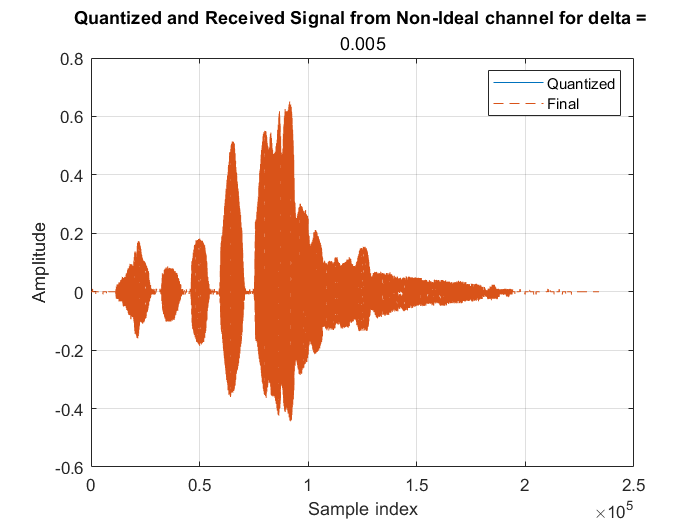

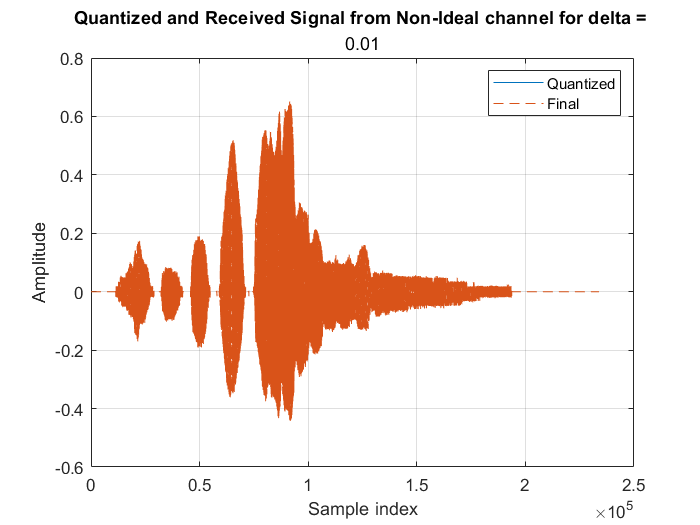

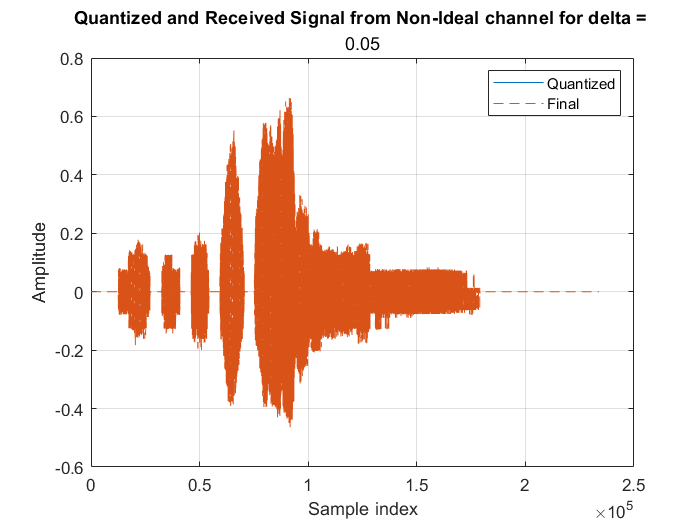

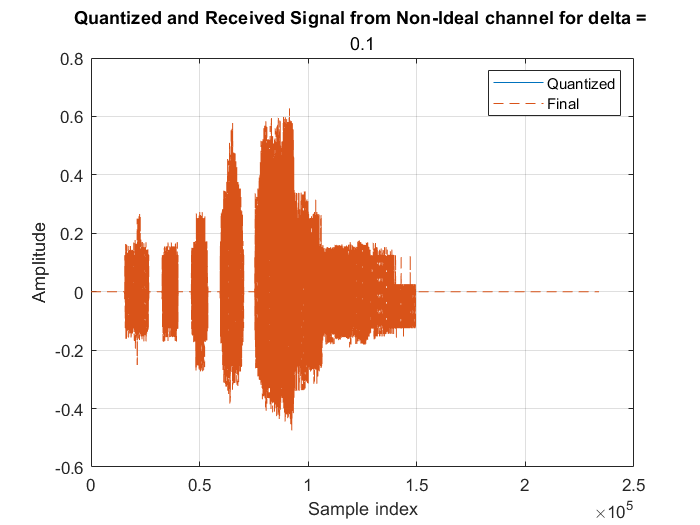

for i = 1:4
    figure;
    plot(Org_Signals(i, :));
    hold on;
    plot(Final_Signals(i, :), '--');
    title('Quantized and Received Signal from Non-Ideal channel for delta = ', delta_vals(i));
    xlabel('Sample index');
    ylabel('Amplitude');
    legend('Quantized','Final');
    grid on;
end

#### Impact of $f_s$

Playing received audio for fs = 1.000000e+03


Playing received audio for fs = 2.000000e+03


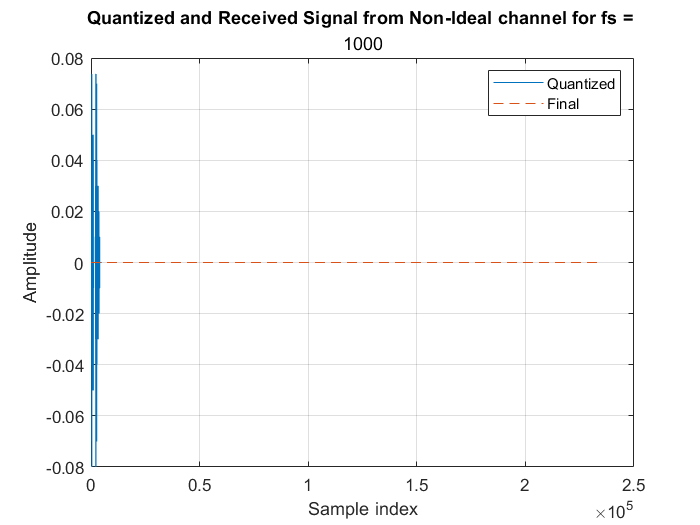

Playing received audio for fs = 4.000000e+03


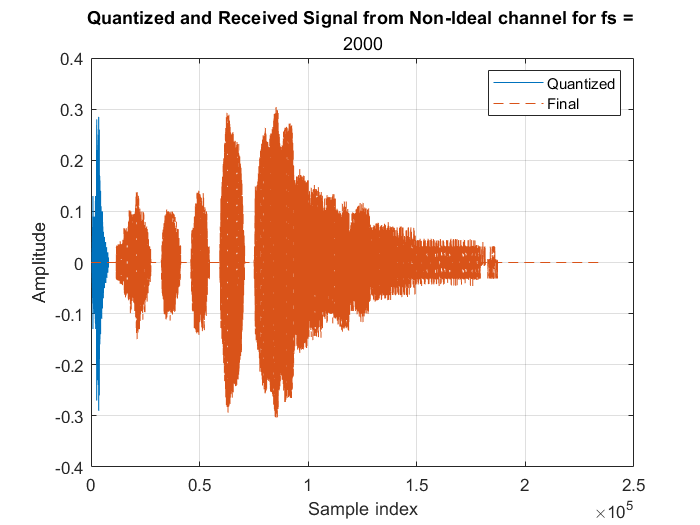

Playing received audio for fs = 1.000000e+04


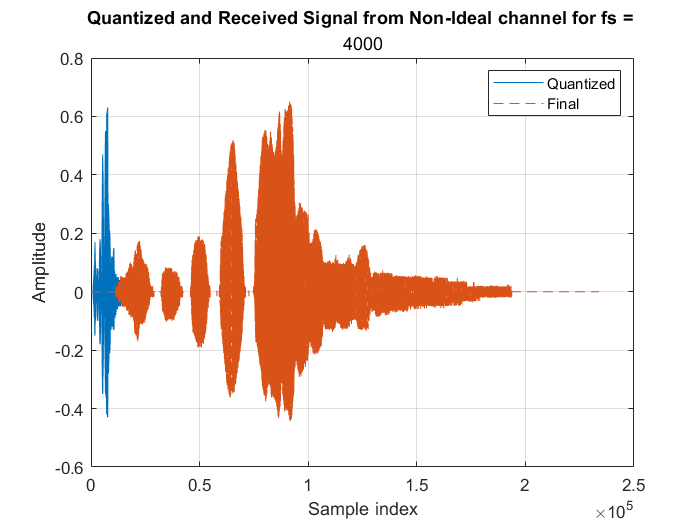

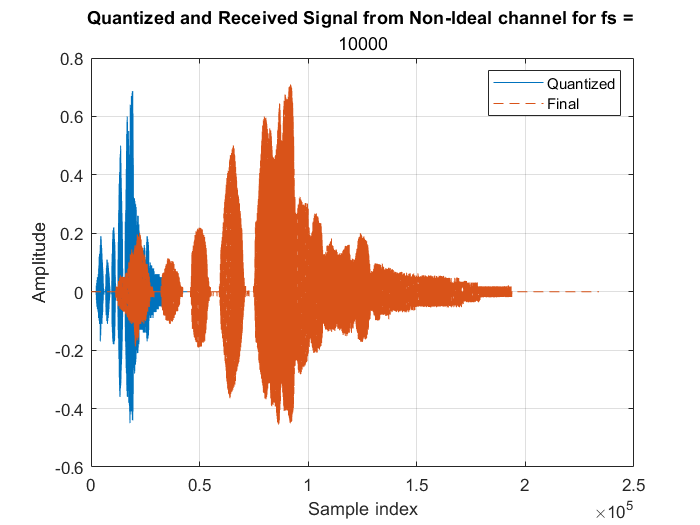

clear;
clc;

filePath  = 'audio.wav';

delta = 0.01;
a = 10;
N0 = 1e-5;
fs_vals = [1000, 2000, 4000, 10000];
r_LC = 499;
fc_ASK = 20000;
BW_CH = 1000;

for f = fs_vals
    [Quantized_Signal, fsUsed, M] = ADC(filePath, f, delta);
    
    [~, Line_Coded] = linecoder(Quantized_Signal, r_LC, a, M);
    [ASK, ~] = ASKModulator(Line_Coded, M, fc_ASK, f, r_LC, a);
    [rx, ~] = channelAWGN(ASK, BW_CH, N0);
    Demodulated = ASKDemodulator(rx, fc_ASK, f, r_LC, a);
    bitsR = lineDecoder(Demodulated, f, r_LC, M);
    final = DAC(bitsR, f, fsUsed);
    
    sound(final, fsUsed);
    fprintf('Playing received audio for fs = %e\n', f);
    pause(5);
    
    figure;
    plot(Quantized_Signal);
    hold on;
    plot(final, '--');
    title('Quantized and Received Signal from Non-Ideal channel for fs = ', f);
    xlabel('Sample index');
    ylabel('Amplitude');
    legend('Quantized','Final');
    grid on;
end

function numbers = binaryToFloat(bin_num, M)

    % Convert bin_num to double
    bin_num = double(bin_num);
    % Extract Sign Bits and Magnitude Bits
    sign_bits = bin_num(:, 1);
    magnitude_bits = bin_num(:, 2:end);
    % Define the fractional powers of two
    frac_bits = M - 1;
    powers_of_two = 2.^(-(1:frac_bits));
    % Calculate magnitudes
    magnitudes = magnitude_bits * powers_of_two';
    % Apply sign
    numbers = magnitudes;
    numbers(sign_bits == 1) = -numbers(sign_bits == 1);
    % Ensure output is a column vector
    numbers = numbers(:);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function bin_str = floatToBinary(numbers, M)

    % Reshape input to a column vector for consistent processing
    numbers = numbers(:);
    % Number of fractional bits
    frac_bits = M - 1;
    % Initialize sign_bits
    sign_bits = repmat('0', length(numbers), 1);
    % Determine sign bits
    negative_indices = numbers < 0;
    sign_bits(negative_indices) = '1';
    % Absolute values for magnitude
    abs_numbers = abs(numbers);
    % Scale numbers
    scaled_numbers = round(abs_numbers * 2^double(frac_bits));
    % Check for overflow
    max_val = 2^frac_bits - 1;
    if any(scaled_numbers > max_val)
        error('One or more numbers are too large to represent with %d bits.', M);
    end
    % Convert magnitudes to binary with leading zeros
    magnitude_bits = dec2bin(scaled_numbers, frac_bits);
    % Combine sign and magnitude bits
    bin_str = [sign_bits, magnitude_bits];
    bin_str = double(bin_str - '0');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [quantized_signal, fs_out, M] = ADC(filePath, fs_in, delta)
    % reading
    [analog_signal, fs_file] = audioread(filePath);
    % taking only one audio chanel
    if size(analog_signal, 2) > 1
        analog_signal = analog_signal(:,1);
    end
    digital_signal = resample(analog_signal, fs_in, fs_file);
    fs_out = fs_file;
    % refrence level
    V_ref = max(abs(digital_signal));
    if V_ref == 0
        quantized_signal = digital_signal;
        return;
    end
    % number of levels
    L = 2 * V_ref / delta;
    M = int8(log2(L));
    % turn amplitude into "steps"
    normalized_signal = digital_signal / delta;
    % Round to the nearest integer to get quantized "levels"
    quantized_levels = round(normalized_signal);
    % Clamp the levels to the range [-L/2, (L/2) - 1]
    % Here we assume a mid-rise uniform quantizer that spans ±V_ref
    lowerBound = -L/2;
    upperBound = (L/2) - 1;
    quantized_levels = max(quantized_levels, lowerBound);
    quantized_levels = min(quantized_levels, upperBound);
    % Convert levels back to signal by multiplying by delta
    quantized_signal = quantized_levels * delta;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [t, lineCodedSignal] = linecoder(qSignal, baudRate, amplitude, M)
    qSignal = qSignal(:).';
    m = double(M);
    numSymbols = length(qSignal);
    T_symbol = 1 / baudRate;
    totalTime = numSymbols * m;
    Ts = T_symbol / m;
    t = 0 : Ts : (totalTime - Ts);
    
    lineCodedSignal = zeros(1, numSymbols * double(m));
    signal_binary = floatToBinary(qSignal, m);
    index = 1;
    for i = 1 : numSymbols
        lineCodedSignal(1, index: index + m - 1) = amplitude * signal_binary(i, :);
        index = index + m;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [passbandSignal, t] = ASKModulator(lineCodedSignal, M, fc, Fs, symbolRate, A)
    M = double(M);
    % 1) Map line-coded signal values to discrete M-ASK amplitude levels
    amplitudeLevels = linspace(0, A, M); % Define M amplitude levels (0 to 1 ASK)
    symbolIndices = round(lineCodedSignal * (M - 1) / A); % Scale line-coded signal to index range
    modulatedSymbols = amplitudeLevels(symbolIndices + 1); % Map indices to amplitude levels

    % 2) Define time vector
    samplesPerSymbol = round(Fs / symbolRate); % Samples per symbol
    totalSamples = length(lineCodedSignal) * samplesPerSymbol; % Total samples for the signal
    t = (0:totalSamples-1) / Fs; % Full time vector

    % 3) Create baseband signal by upsampling the symbols
    basebandSignal = repelem(modulatedSymbols, samplesPerSymbol); % Repeat each symbol for its duration

    % 4) Multiply by carrier to generate passband signal
    passbandSignal = basebandSignal .* cos(2 * pi * fc * t);
end




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [rxSignal, noiseVec] = channelAWGN(txSignal, B, N0)
    % Compute noise variance = N0 * B
    sigma2 = N0 * B;
    sigma  = sqrt(sigma2);
    % Generate additive white Gaussian noise
    noiseVec = sigma * randn(size(txSignal));
    % Add noise to the transmitted signal
    rxSignal = txSignal + noiseVec;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function recoveredSignal = ASKDemodulator(passbandSignal, fc, Fs, symbolRate, A)
    
    % 1) Define time vector
    nSamples = length(passbandSignal);
    t = (0:nSamples-1) / Fs;

    % 2) Coherent demodulation (Multiply by synchronized carrier)
    demodulatedSignal = passbandSignal .* cos(2 * pi * fc * t);

    % 3) Envelope detection (Rectification)
    rectifiedSignal = abs(demodulatedSignal);

    % 4) Low-pass filter to extract baseband signal
    cutoffFrequency = symbolRate ; % Half of the symbol rate
    Wn = cutoffFrequency / (Fs / 2);  % Normalized cutoff frequency
    filterOrder = 16;  % Order of Butterworth filter
    
    [b, a] = butter(filterOrder, Wn, 'low');
    basebandSignal = filtfilt(b, a, rectifiedSignal); % Zero-phase filtering

    % 5) Symbol sampling
    samplesPerSymbol = round(Fs / symbolRate);
    sampledSymbols = basebandSignal(1:samplesPerSymbol:end); % Sample at symbol intervals

    % 6) Threshold decision for binary output
    recoveredSignal = sampledSymbols > A/2; % Output 1 if above threshold, else 0
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function bitsOut = lineDecoder(lineCodedSignal, Fs, baudRate, M)

    lineCodedSignal = lineCodedSignal(:).';
    samplesPerBit = round(Fs / baudRate);
    N = length(lineCodedSignal);
    m = double(M);
    numSample = floor(N / m);
    % Reshape so each column is one bit's worth of samples
    bits = reshape(lineCodedSignal, [m numSample]);
    [~, cols] = size(bits);
    bitsOut = zeros(1,cols);
    for i = 1 : cols
        bitsOut(1, i) = binaryToFloat(bits(:,i).', m);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function output_signal = DAC(Signal, Fs, Fs_main)
    % Time vectors for original and interpolated data
    t_digital = (1:length(Signal)) / Fs;
    t_analog = linspace(1/Fs, length(Signal) / Fs, 1 * length(Signal));
    chunk_out = interp1(t_digital, Signal, t_analog, 'linear', 'extrap');
   % Append processed chunk to final output
    output_signal = chunk_out;
    output_signal = resample(output_signal, Fs_main, Fs);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [rxSignal, noiseVec] = NonIdealChannel(txSignal, fs, B, N0)
    % Compute noise variance
    sigma2 = N0 * B;
    sigma  = sqrt(sigma2);

    % Design a Low-Pass Filter (LPF) to impose bandwidth limitation
    Wn = (B / (fs / 2));  % Normalized cutoff frequency
    filterOrder = 10; % Higher order makes sharper cutoff
    [b, a] = butter(filterOrder, Wn, 'low');

    % Pass the transmitted signal through the Band-Limited Channel
    filteredSignal = filtfilt(b, a, txSignal);

    % Generate AWGN noise
    noiseVec = sigma * randn(size(filteredSignal));

    % Add noise to the signal
    rxSignal = filteredSignal + noiseVec;
end

